# Signals #4: DtFT vs. DFT

## Discretization of continuous Fourier transform and Fourier series

Continuous Fourier transform (CFT) and Fouries series (FS) are defined as follows for analog signals (non-period and periodic ones, respectively):

(CFT)  $X(f) = \int_{-\infty}^{+\infty} { x(t) e^{-j2\pi ft} dt}$,

(FS)    $X(kf_0) = \frac{1}{T}\int_{0}^{T} { x(t) e^{-j2\pi (kf_0)t} dt}, \quad k=0, \pm 1, \pm 2, \pm 3, ... , \quad f_0=\frac{1}{T}.$

After time discretization ($f_s$ - sampling frequency, $dt=1/f_s$) and assuming having only $$N$$ signal samples ($n=0,1,2,...,N-1$, $t=n \cdot dt$), we obtain discrete versions of CFT and FS, knowns as Distrete time Fourier Transform (DtFT) and Discrete Fourier Transform (DFT):

(DtFT)   $X(f)=\frac{1}{N} \sum_{n=0}^{N-1} x(n) e^{-j2\pi (f/f_s) n}$

(DFT)    $X(kf_0)=\frac{1}{N} \sum_{n=0}^{N-1} x(n) e^{-j 2\pi (kf_0/f_s) n}=\frac{1}{N} \sum_{n=0}^{N-1} x(n) e^{-j (2\pi/N)kn}, \quad k=0,1,2,...,N-1.$

As we see equations are almost the same, the only difference is that in DtFT the frequency choice is arbitrary while in DFT - obligatory. This results from the fact that  when the signal is periodic it can contain only frequencies beeing multiplies of its fundamental frequency $f_0=\frac{1}{T}$ ( $T=N \cdot dt$- signal time duration). In our present program we will concentrate on basics of frequency analysis using DtFT and DFT. 

## Analyzed signal

Signal of our interest:

- will be sampled with frequency $f_s$,

- will have $N$ samples,

- will consists of two cosines with amplitudes $A_1, A_2$ and frequencies $f_1, f_2$: $x(t) = A_1 \cos(2\pi f_1 t) + A_2 \cos(2\pi f_2 t)$.

Signal component amplitudes can differ a lot (problem with available **amplitude resolution** of the frequency analysis: how to see amplitude that is so small?) and signal component frequencies can be very similar (problem with available **frequency resolution** of the frequency analysis: how to distinguish frequencies which lies so close).

**Analyze the Matlab code. **Generate different signals and observe their shapes.

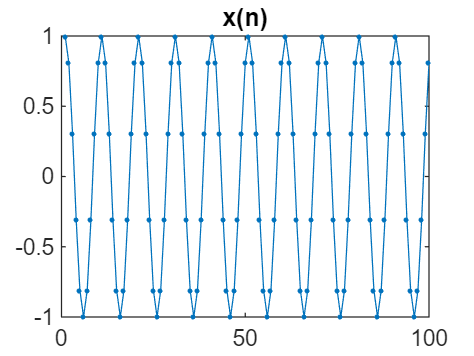

% clear all; close all;

% Signal
N = 100;                            % number of samples: 100 --> 1000
fs = 1000; dt=1/fs; t=dt*(0:N-1);   % sampling ratio
fx1 = 100;  Ax1 =1;                 % frequency and amplitude of signal component 1
fx2 = 250;  Ax2 =1;                 % frequency and amplitude of signal component 2
                                    % 250 --> 110, 0 --> 0.001 --> 0.00001
x1 = Ax1*cos(2*pi*fx1*t);           % first component
x2 = Ax2*cos(2*pi*fx2*t);           % fx2 250Hz --> 110Hz, Ax2 1 --> 0.001 --> 0.00001
x = x1; % + x2;                     % x1, x1+x2, 20*log10(0.00001)=-100 dB
plot(x,'.-'); title('x(n)');        % analyzed signal

## Window selection

In order to improve amplitude resolution, appropriate **window function** (Hamming, Hanning, Blackman, Kaiser, Chebyshev, ...) should be used which performs smooth tapering the signal shape on its begining and end, and remove possible sharp signal changes on its edges. 

**Analyze the Matlab code**. Add more window functions to the program, observe its shapes as well as shapes of the signal after different "windowing".

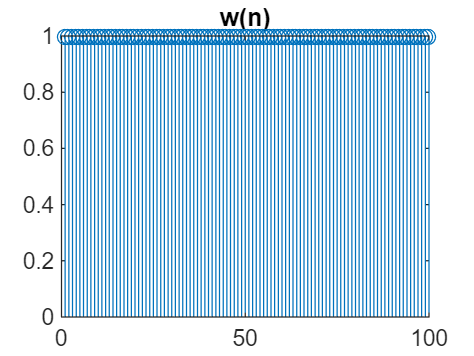

% Windowing
w1 = boxcar(N)';                    % rectangular window
w2 = hanning(N)';                   % Hanning window
w3 = chebwin(N,140)';               % Chebyshev window: 80,100,120,140
w = w1; is_w1=1;                    % w1 --> w2, w3 (80,100,120,140)
figure; stem(w); title('w(n)');     % window

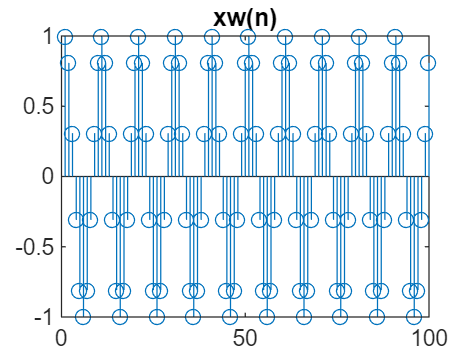

x = x .* w;                         % x = x, w, x.*w
figure; stem(x); title('xw(n)');    % windowed signal

## DtFT and DFT computation

**Analyze the Matlab code** in which DtFT and DFT are computed according to their definitions, given above.  Change  `df,fmax`  of DtFT and compare obtained shape of the DtFT spectrum with the DFT spectrum, which should be the same in all experiments. As you see the DtFT spectrum is periodical and it is sufficient to compute DtFT only in the interval/range $\left[ -\frac{f_s}{2}, +\frac{f_s}{2} \right)$ or $\left[ 0, f_s \right)$. Setting `df` to a small value we can sample the DtFT spectrum more dense than in DFT (always with the step $f_0=f_s/N$) . Change values of $f_s, N$and observe these features.

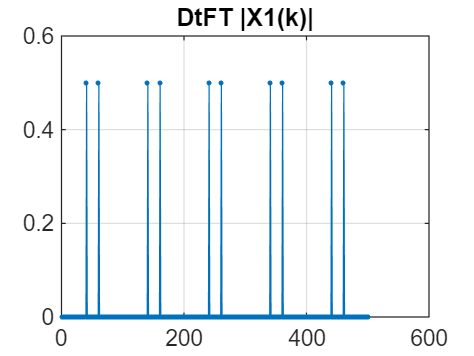

% DtFT - already discussed (blue line)
df = 10;                  % sampling step:  10 --> 1
fmax = 2.5*fs;            % sampling range: 2.5 --> 0.5
f1=-fmax:df:fmax;         % frequency range 
for k = 1 : length(f1)
    X1(k) = sum( x .* exp(-j*2*pi* (f1(k)/fs) *( 0:N-1) ) ) / N;
end
if(is_w1==1) X1 = N*X1/sum(w); end % scaling for any window different from rectangular
figure; plot(abs(X1),'.-'); title('DtFT |X1(k)|'); grid;  % showing result

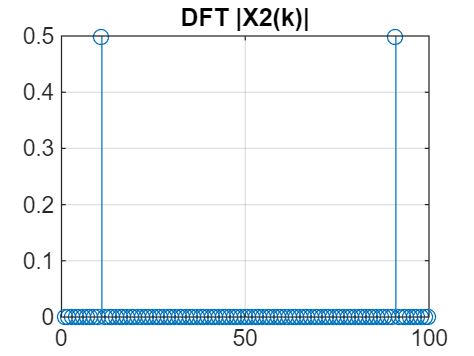


% DFT - later in this chapter (red circles)
% k=0:N-1; n=0:N-1; F = exp(-j*2*pi*(k'*n)); X = (1/N)*F*x;
f0 = fs/N; f2 = f0*(0:N-1);        % DFT freq step = f0 = 1/(N*dt)
for k = 1:N
    X2(k) = sum( x .* exp(-j*2*pi/N* (k-1) *(0:N-1) ) )/ N;       % the same
  % X2(k) = sum( x .* exp(-j*2*pi/N* (f2(k)/fs) *(0:N-1) ) )/ N;  % the same
end
if(is_w1==1) X2 = N*X2/sum(w); end % scaling for any window different from rectangular
figure; stem(abs(X2)); title('DFT |X2(k)|'); grid;  % showing result

## Detailed comparison of DtFT and DFT spectra

**Modify the Matlab code**. These figures can help us with better understanding the difference between the DtFT (dense frequency sampling but extensive computing) and DFT (for fixed values of $f_s, N$ sampling of the spectrum is constant but very fast algorithms exist for the DFT computation).

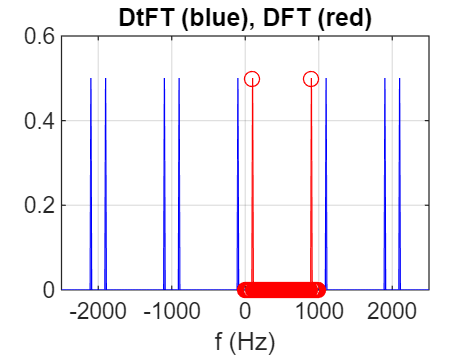

% Figures
figure; plot(f1,abs(X1),'b-',f2,abs(X2),'ro-');
xlabel('f (Hz)'); title('DtFT (blue), DFT (red)'); grid;

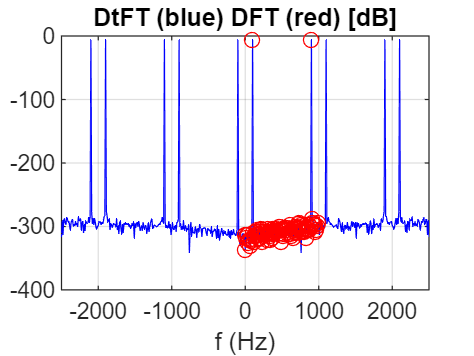

figure; plot(f1,20*log10(abs(X1)),'b-',f2,20*log10(abs(X2)),'ro');
xlabel('f (Hz)'); title('DtFT (blue) DFT (red) [dB]'); grid;

- Set  `df=1; fmax=fs/2, x = w.` Observe spectrum of different windows alone. Note different width of their spectral main-lobe around 0Hz, and different "attentuation" level of spectral side-lobes.

- Set  x=x1`; w=w1;` Observe spectrum of a pure strong cosine computed with rectangular window. Can you read out cosine amplitude and frequency from the figure?  

- Set  x=x1+x2`; fx2=250; Ax2=1; w=w1;` Do you see the second component? I think that yes.

- Let 's make the second component weaker. Set  x=x1+x2`; fx2=250; Ax2=0.001; w=w1;` Do you see the second component? I think that do not.

- Let's take better window with higher attentuation of spectral side-lobes. Now set `w=w3; (with Asl=120).` At present you should see the second component.

- Let's shift the second component in frequency closer to the first one. Set x=x1+x2`; fx2=110; Ax2=0.001; w=w3; (with 120). `Do you see the second component? Not very good?

- Let's take more signal samples. Set `N=1000. `Is the spectrum sharper?